A=[1 2 3; 4 5 6; 9 8 6]

A =      1     2     3
     4     5     6
     9     8     6


A=[1 2 3; 4 5 6; 9 8 6];
A(2,1)

ans = 4

A(2,2)

ans = 5

A(2,1:2)

ans =      4     5


A(1:2,2:3)

ans =      2     3
     5     6


A(1:2,:)

ans =      1     2     3
     4     5     6


size(A)

ans =      3     3


A'

ans =      1     4     9
     2     5     8
     3     6     6


inv(A)

ans =    -6.0000    4.0000   -1.0000
   10.0000   -7.0000    2.0000
   -4.3333    3.3333   -1.0000


A*inv(A)

ans =     1.0000   -0.0000    0.0000
    0.0000    1.0000    0.0000
    0.0000   -0.0000    1.0000


sum(A) % summerer kolonner

ans =     14    15    15


sum(A')

ans =      6    15    23


zeros(3,2)

ans =      0     0
     0     0
     0     0


B=ones(3,2)

B =      1     1
     1     1
     1     1


B*B'

ans =      2     2     2
     2     2     2
     2     2     2


B.*B

ans =      1     1
     1     1
     1     1


b=1:10;
c=ones(size(b))

c =      1     1     1     1     1     1     1     1     1     1


c=ones(1,10)

c =      1     1     1     1     1     1     1     1     1     1


sum(b) %don't use loops if you can avoid it!!!

ans = 55

b*c'

ans = 55

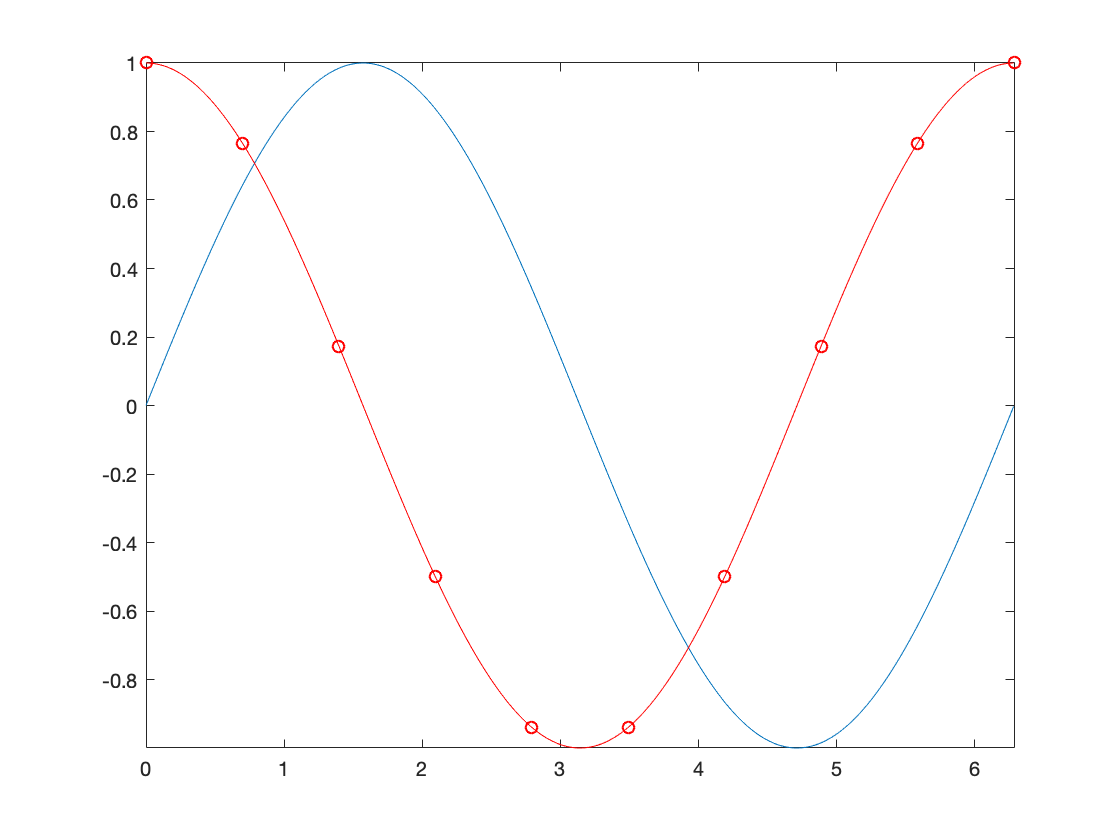

a=0:0.01:2*pi;
plot(a,sin(a))
hold on
plot(a,cos(a),'r')
b=linspace(0,2*pi,10);
plot(b,cos(b),'ro')
hold off
axis tight

%dock figur
%ordne vinduer
%kopier Command History -> Editor
help rand

 rand Uniformly distributed pseudorandom numbers.
    R = rand(N) returns an N-by-N matrix containing pseudorandom values drawn
    from the standard uniform distribution on the open interval(0,1).  rand(M,N)
    or rand([M,N]) returns an M-by-N matrix.  rand(M,N,P,...) or
    rand([M,N,P,...]) returns an M-by-N-by-P-by-... array.  rand returns a
    scalar.  rand(SIZE(A)) returns an array the same size as A.
 
    Note: The size inputs M, N, P, ... should be nonnegative integers.
    Negative integers are treated as 0.
 
    R = rand(..., CLASSNAME) returns an array of uniform values of the 
    specified class. CLASSNAME can be 'double' or 'single'.
 
    R = rand(..., 'like', Y) returns an array of uniform values of the 
    same class as Y.
 
    The sequence of numbers produced by rand is determin

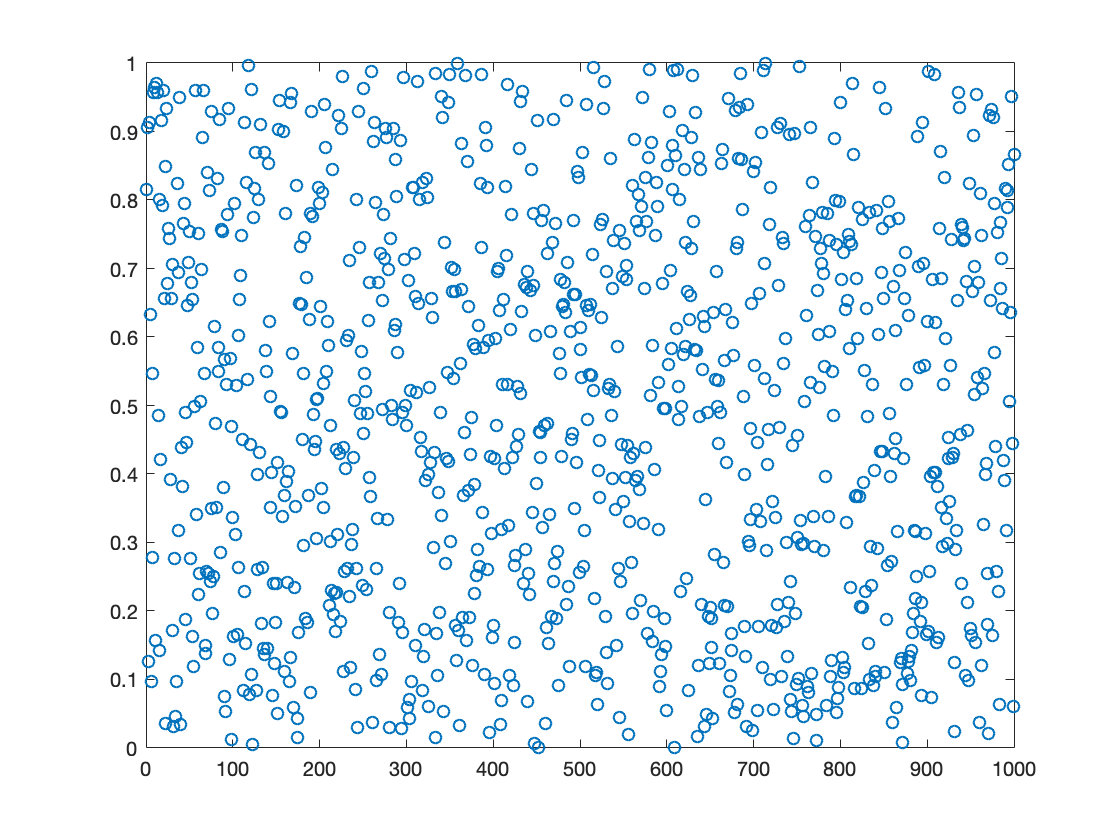

a=rand(1,1000);
plot(a,'o')

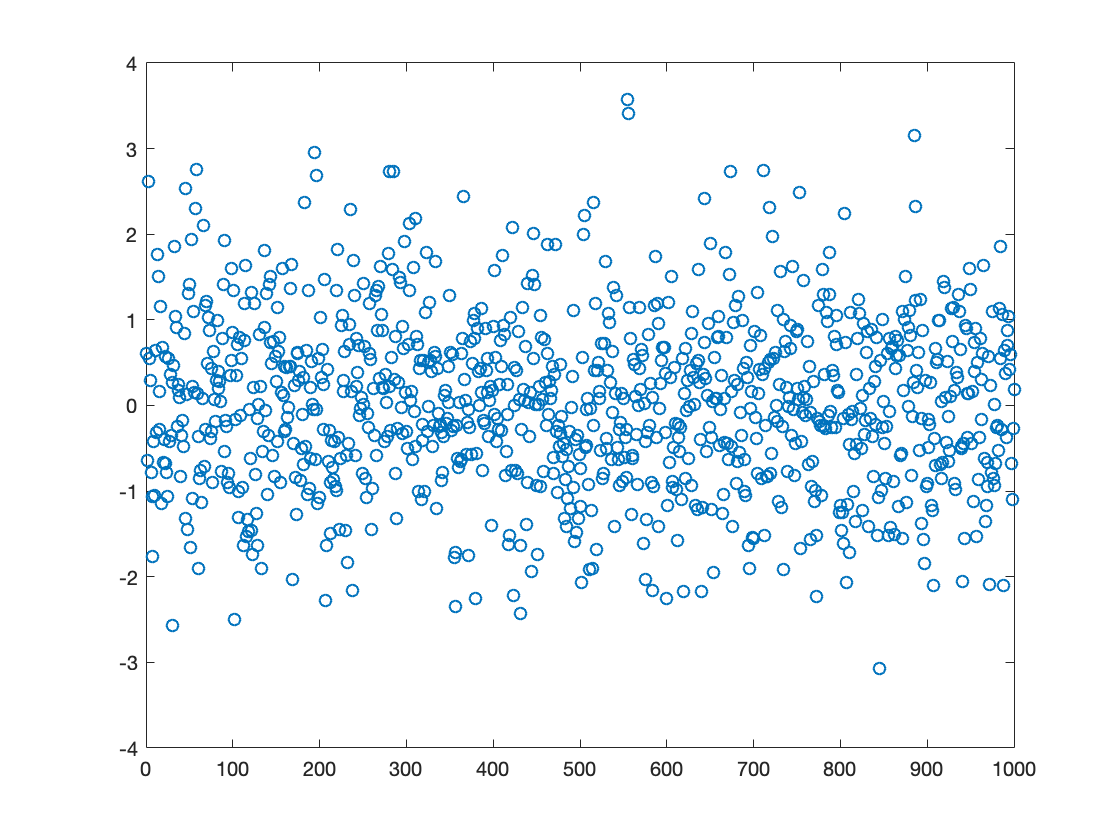

figure
b=randn(1,1000);
plot(b,'o')

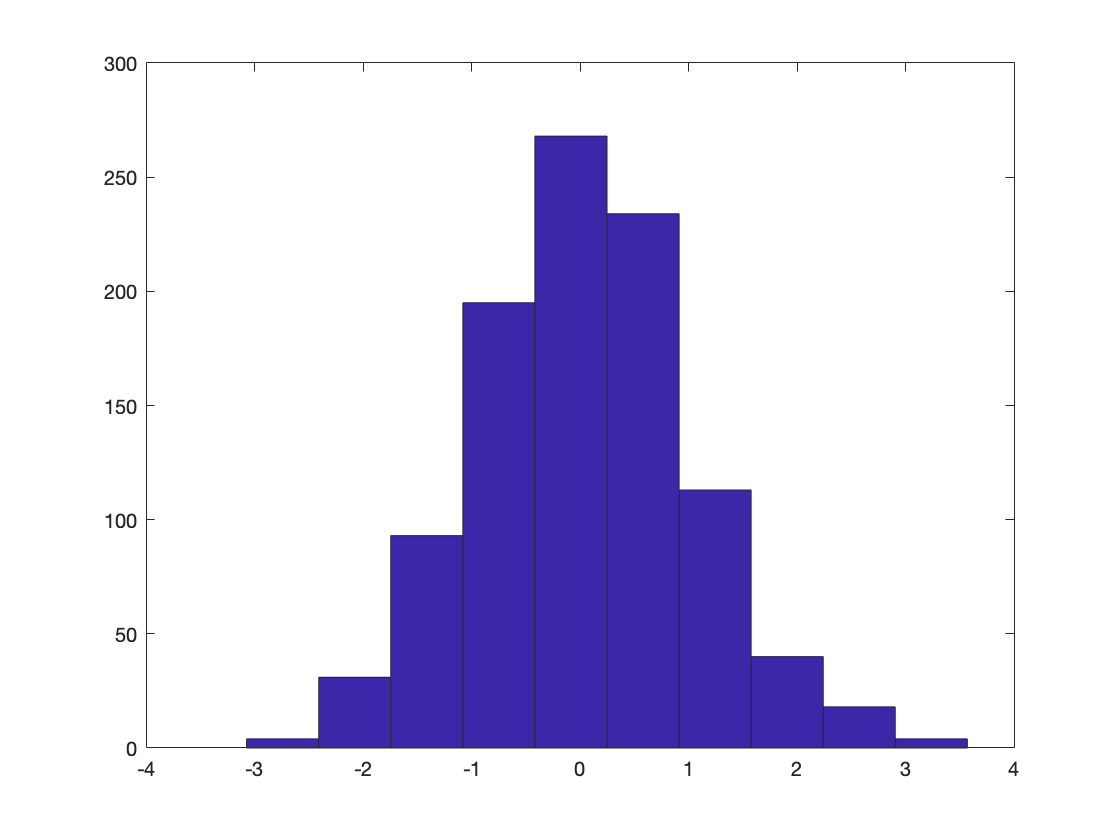

hist(b)

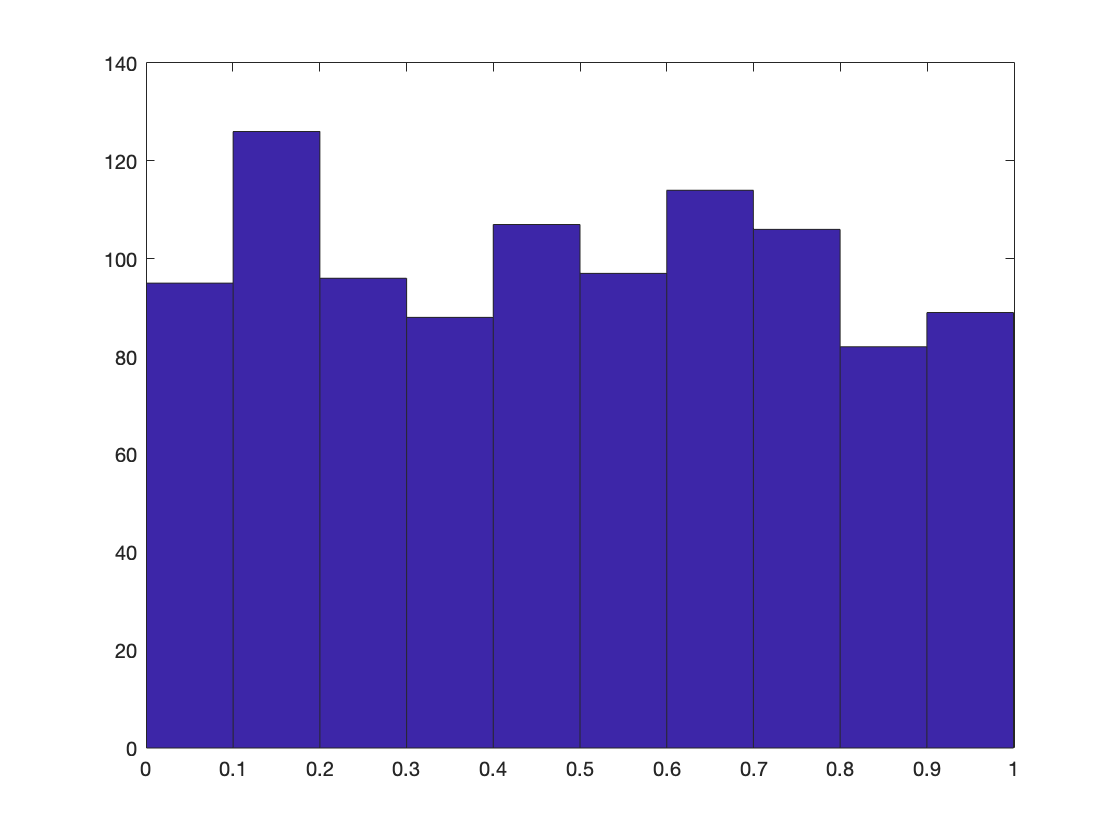

figure(1)
hist(a)

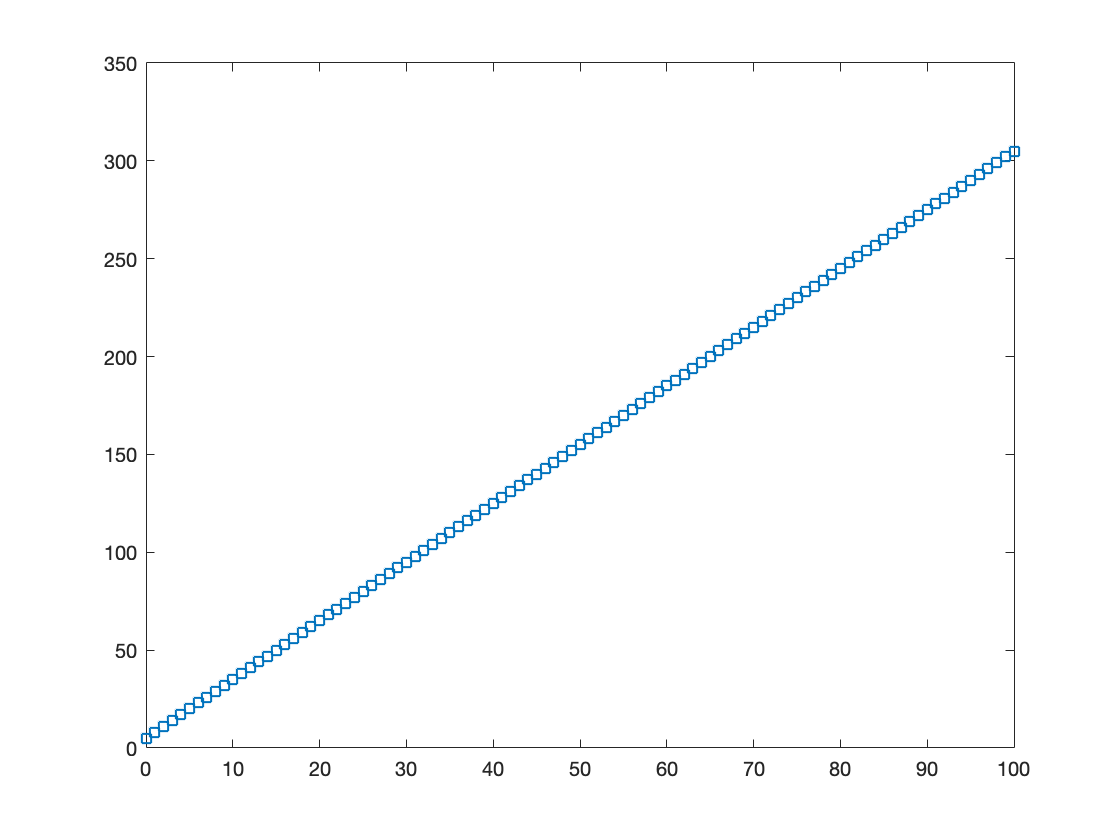

x=0:100;
y=3*x+5;
plot(x,y,'s')

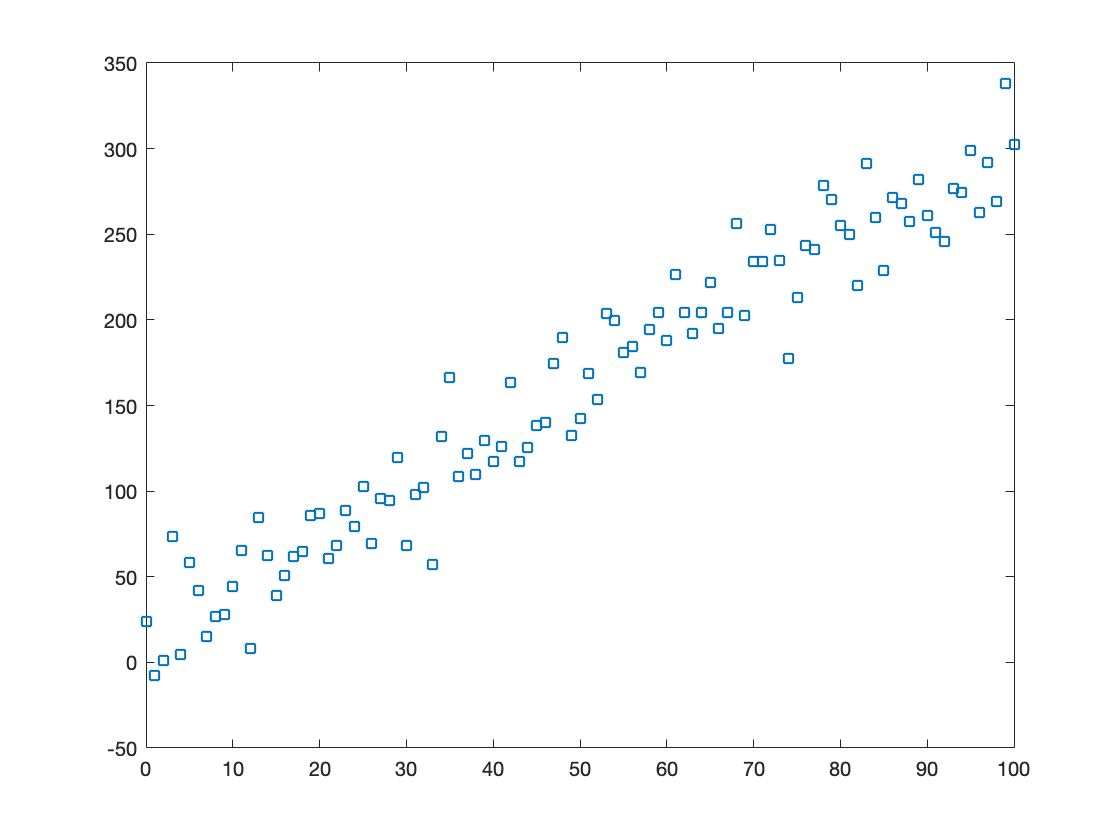

%%
figure(1)
y=3*x+5+20*randn(size(x));
plot(x,y,'s')

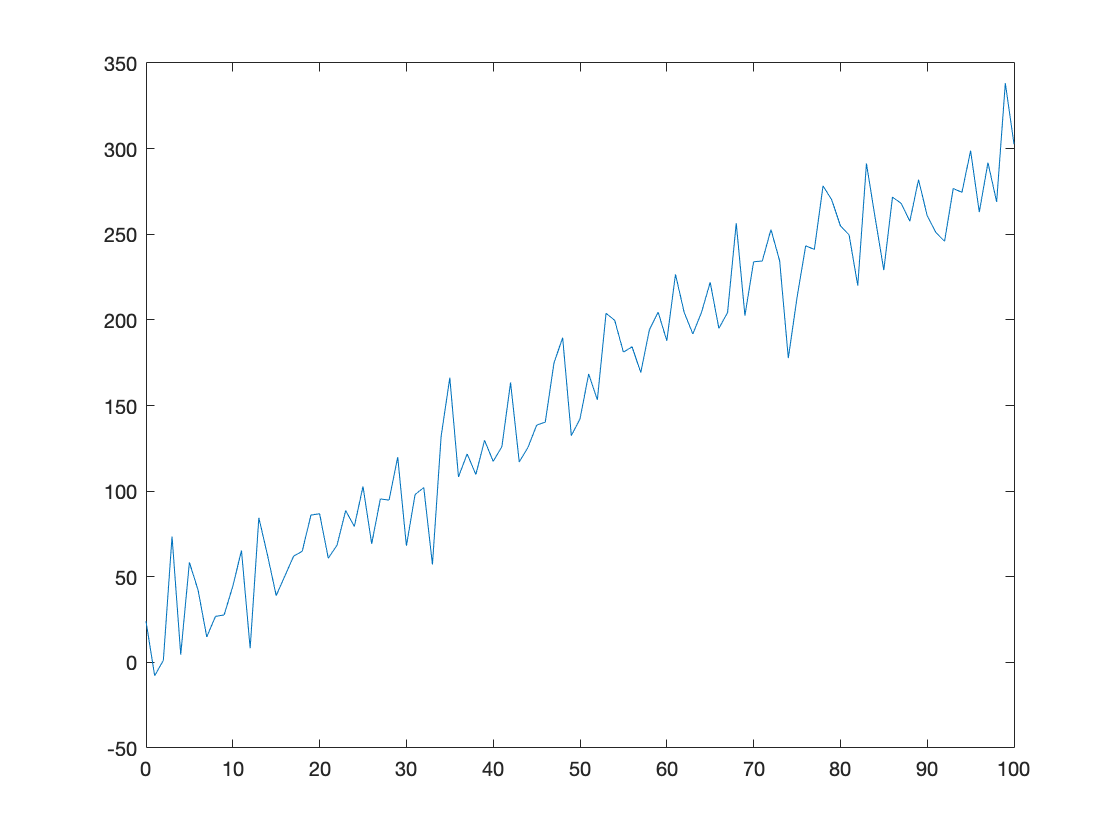

plot(x,y)

plot(x,y,'s')
help polyfit

 polyfit Fit polynomial to data.
    P = polyfit(X,Y,N) finds the coefficients of a polynomial P(X) of
    degree N that fits the data Y best in a least-squares sense. P is a
    row vector of length N+1 containing the polynomial coefficients in
    descending powers, P(1)*X^N + P(2)*X^(N-1) +...+ P(N)*X + P(N+1).
 
    [P,S] = polyfit(X,Y,N) returns the polynomial coefficients P and a
    structure S for use with POLYVAL to obtain error estimates for
    predictions.  S contains fields for the triangular factor (R) from a QR
    decomposition of the Vandermonde matrix of X, the degrees of freedom
    (df), and the norm of the residuals (normr).  If the data Y are random,
    an estimate of the covariance matrix of P is (Rinv*Rinv')*normr^2/df,
    where Rinv is the inverse of R.
 
    [P,S,MU] = polyfit(X,Y,N) finds the coefficients of a polynomial in
    XHAT = (X-MU(1))/MU(2) where MU(1) = MEAN(X) and MU(2) = STD(X)

[p,s]=polyfit(x,y,1) %ikke nøyaktig 3 og 5

p =     2.8931   15.2330


s = struct with fields:
        R: [2×2 double]
       df: 99
    normr: 214.7382


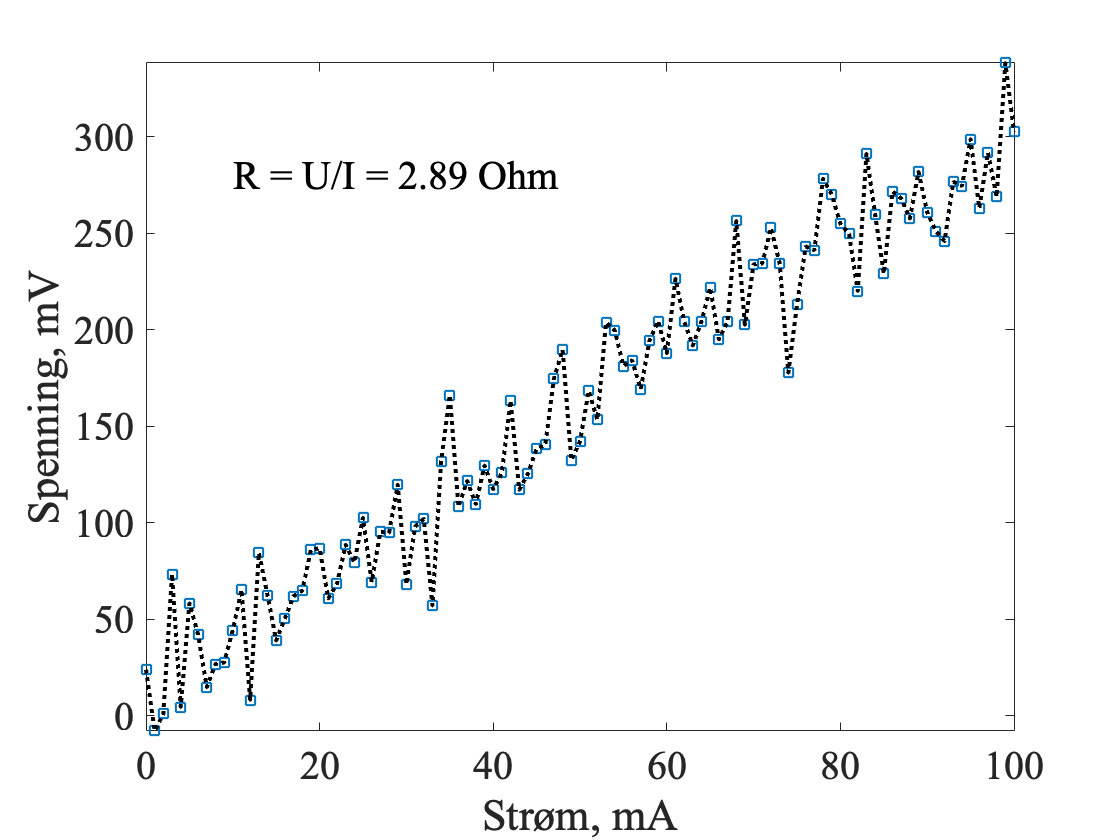

hold on, plot(x,y,'k:','LineWidth',2), hold off
xlabel('Strøm, mA','FontSize',20,'FontName','Times')
ylabel('Spenning, mV','FontSize',20,'FontName','Times')
text(10,280,['R = U/I = ',num2str(p(1),3),' Ohm'],'FontSize',20,'FontName','Times')
set(gca,'FontName','Times')
set(gca,'FontSize',20)
axis tight

%Store nok fonter!
%Data markert med punkter, ikke linjer mellom punktene
%Modelltilpasning til data markert med tydelig linje
